# matlab2word

## Library description

This is a library that allows you to transfer your calculations into an MS Word template file. It might be useful when you have a report template that has specific formatting and requires some calculations.

MS Word has good tools for formatting, but its VBA scripting language is poor in calculations. Otherwise, MATLAB is excellent for calculations and data processing. There are some tools for report generation in MATLAB too. These tools can create a report through coding which is a bit counterintuitive. My library allows you to format report files in Word, do calculations in MATLAB and combine the result into one file.

## Word document preparation 

Create a new Word file and put here id strings (as shown in the picture below) which will be replaced by calculated data. Id strings should be concluded in triangle brackets `<>`. Consider that id strings in the equation area should be typed without *italic* font style, it is important for finding these strings in the equation area.

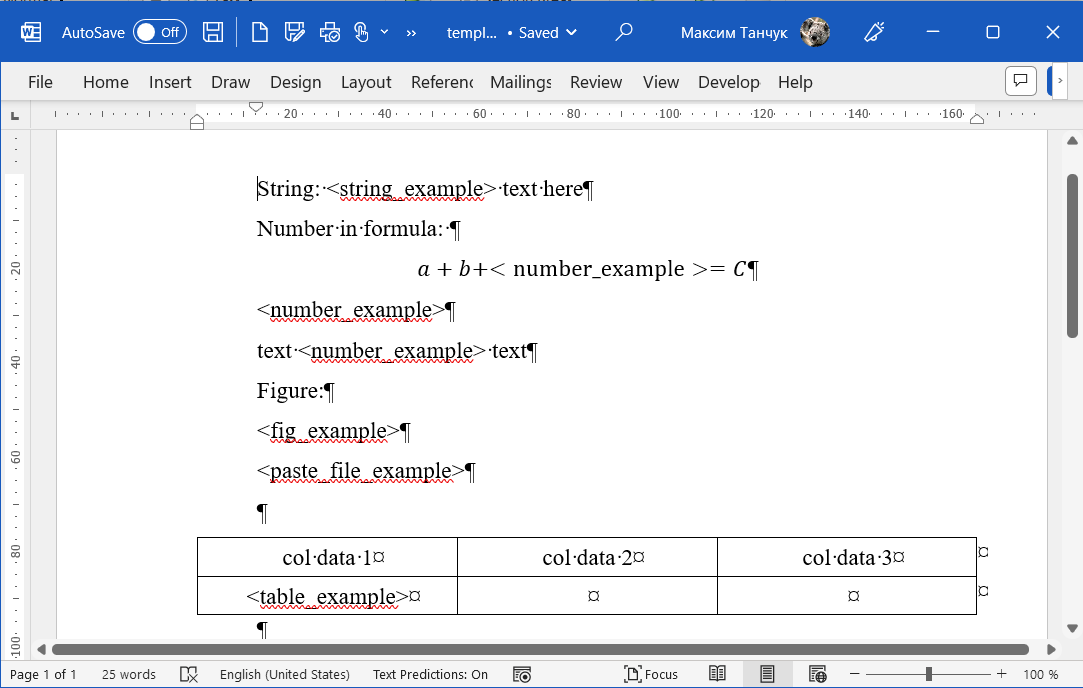

After creating your report template save it with the **.docx** extension and fully close your Word application (including windows with other files).

## Example of calculations

clc, clear, close all;

Let your calculations look like this.

test_string = 'Hello';
test_num = 38600000000000000000-0.000000000013i;
% Create test figure
x = (-4*pi):(8*pi/1000):(4*pi);
f_x_sin_x = sin(x);
fig1 = figure(1); % Here you need to store the figure handler
plot(x, f_x_sin_x);

Here you have typical string, number, and figure examples. Let's transfer them into Word.

## Transfering to Word

First, you must create an instance of your Word document to get access to it. Type:

% Create an instance of matlab2word object and get access to Word file
% m2w = matlab2word();

This command asks you to select a template file and opens it. Alternatively, you can specify your file name by code with a `matlab2word` function argument like this:

m2w = matlab2word('template.docx');

By default, MATLAB uses a *dot* as a decimal separator, you can change it to a *comma* with the command:

m2w.SetDecimalSeparator(',');

By default, MATLAB uses *i* as an imaginary unit in complex numbers, you can change it to *j* with the command:

m2w.SetImaginaryUnit('j');

Then just replace your id strings with calculated data using `Replace`method:

m2w.Replace('string_example', test_string);
m2w.Replace('number_example', test_num);
m2w.Replace('fig_example', fig1);

The replacement method takes 2 arguments. First is the id string from the Word document, and second is the variable in MATLAB. Replacement commands might take some time to run.

### Replacement using data from other file

The library allows using data for replacement not only from MATLAB but also from other Word files. Use the `PasteFile`method for such a replacement and provide 2 arguments (1- id string for replace; 2 - filename from which data will be taken)

m2w.PasteFile('paste_file_example', 'template1.docx');
m2w.Replace('pasted_file_insert_test', 'Another text');

### Replacement of table data

The library allows replacing data in a table with an undefined number of rows. You can specify such a table in MATLAB either with a 2-dimensional array or with a table variable. There is only one requirement for correct replacement: the number of columns in the Word template must be equal to the number of columns in the MATLAB variable.

t1 = [1, 2, 3; 4, 5, 6];
t1 = table([1; 4], ["ab"; "cd"], [3+5i; -67i]);

Replace by using the following command:

m2w.PasteTable('table_example', t1);

## Saving file

At the end save your report by command:

m2w.Save();

This command saves the file automatically by adding the _out part to your input file.

If you prefer another name or path, you can specify it explicitly as well as for the input file.

% m2w.Save('output_file_name.docx');

Also you can select output file during script running by using the following command:

% m2w.SaveManually();

(in this case system window will be opened for selecting the file path).